clear, clc

## LOAD DATA 

path = 'D:\University programming\MATLAB\Module 12\Neuron Parameter Estimation\Trial Information';
for MVC = 10:10:70
    names{MVC/10} = [num2str(MVC) '_MVC_with_BISI'];
    names2{MVC/10} = [num2str(MVC) '_MVC_no_BISI'];
end
for i = 1:7
    data(i) = load([path '\' names{i} '.mat']);
    data2(i) = load([path '\' names2{i} '.mat']);
end
clear path, clear names, clear names2, clear i, clear MVC

## PLOT THE SELECTED NEURONS

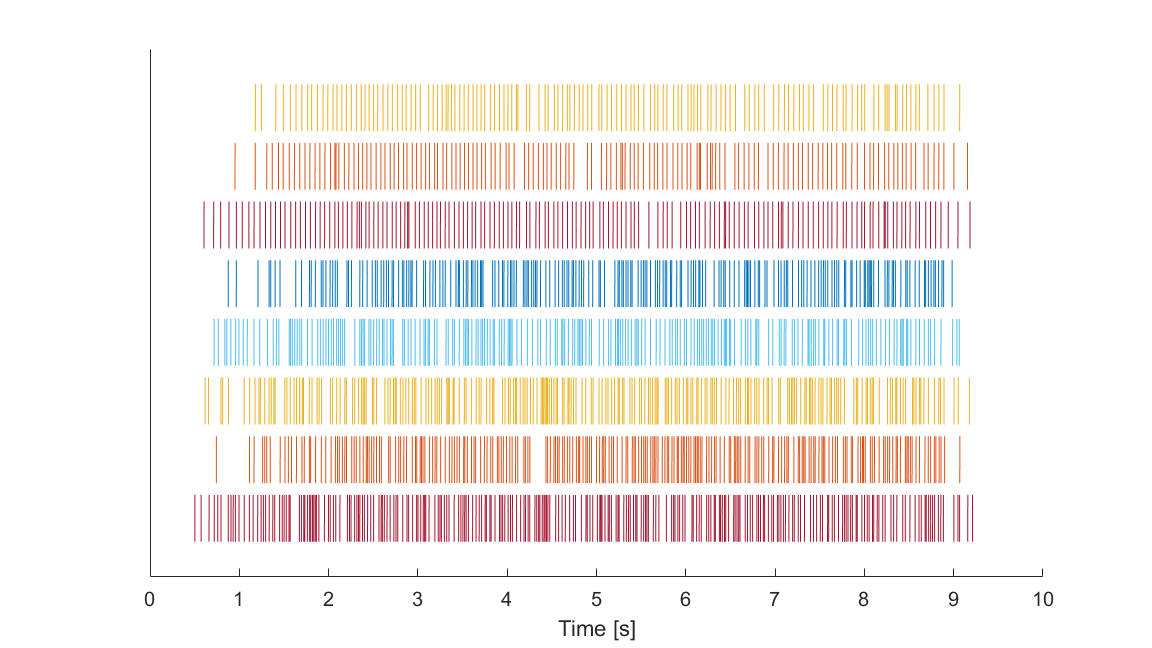

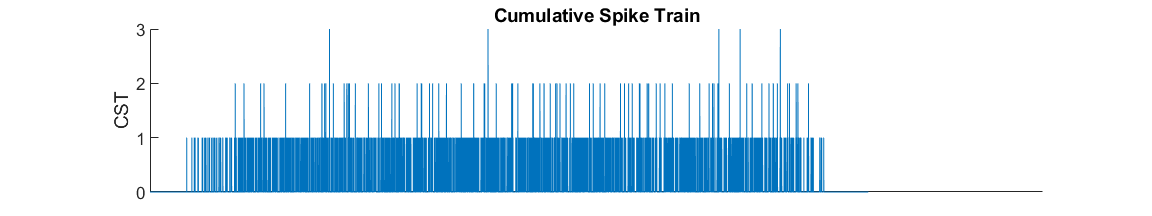

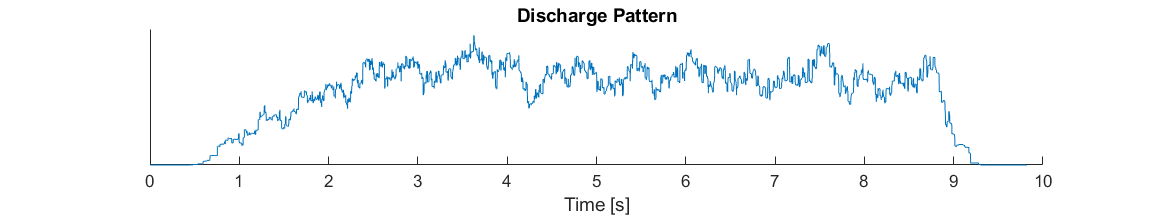

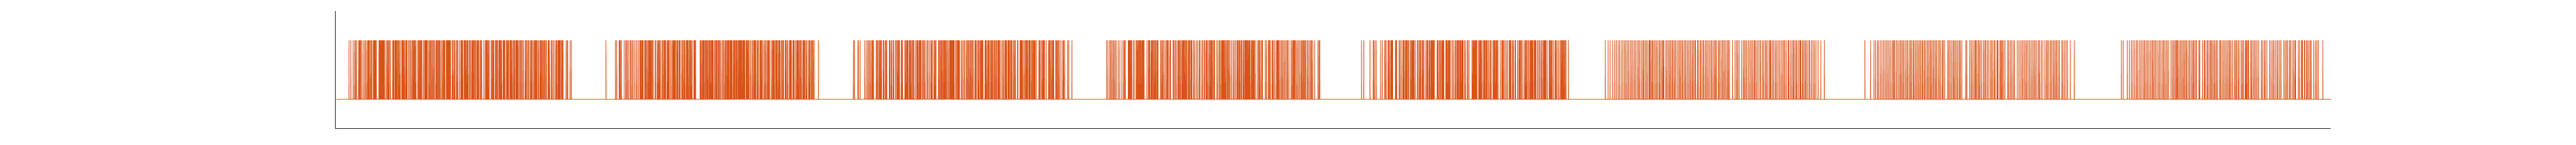

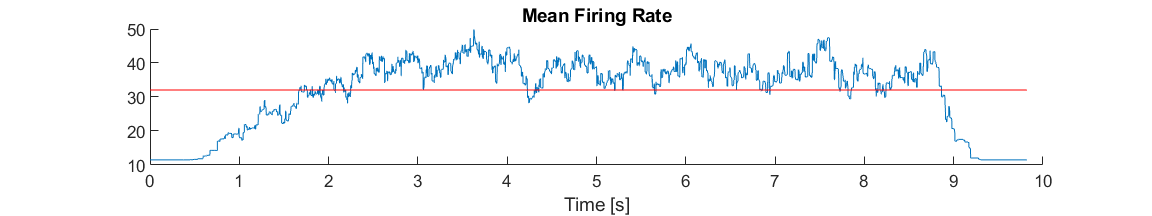

timecor = [0.7 0.4 0.7;
    1.2 0.6 0.8;
    1.4 0.7 1.1;
    1.2 0.4 0.7;
    0.7 1.2 1.4;
    1.2 0.6 0.7;
    1.4 1.2 1.1];
MVCs = 2;
TRIAL = 2;
for MVC = MVCs
    for trial = TRIAL
        %% Collent data
        % just colors
        color = {'#A2142F','#D95319','#EDB120','#4DBEEE','#0072BD'};
        linWidth = 0.5;
        colSeq = 1;
        % Selected neurons
        SelNeurons = data(MVC).Trial_corr(trial).QCids.Selected;
        SelNeurons2 = data(MVC).Trial(trial).QCids.Selected;
        SelNeurons3 = data2(MVC).Trial(trial).QCids.Selected;
        
        %% Star Plotting
        figure, clf, hold on
        spikeTrains = zeros(length(data(MVC).Trial(trial).tVec),length(SelNeurons3));
        
        %% Sublot 1 & 2
        for muCount = 1:length(data(MVC).Trial(trial).MUPulses_vec(SelNeurons3))
            t2 = repelem(data(MVC).Trial(trial).tVec,2);
            spikePos = (data(MVC).Trial(trial).MUPulses_vec{muCount})*2;
            spikePos2 = (data(MVC).Trial(trial).MUPulses_vec{muCount});
            
            for muCount2 = 1:length(spikePos2)
                spikeTrains(spikePos2(muCount2),muCount) = 1;
            end
            plotVar = NaN(size(t2));
            if ~isempty(spikePos)
                plotVar(spikePos) = muCount-0.4;
                plotVar(spikePos+1) = muCount+0.4;
            end
            plot(t2,plotVar,'-','Color',color{colSeq},'LineWidth',linWidth);
            if colSeq < 5
                colSeq = colSeq + 1 ;
            else
                colSeq = 1;
            end
        end
        yticks([])
        xlabel('Time [s]')
        
        % plot final params
        set(gcf, 'units', 'normalized');
        set(gcf, 'Position', [0, 0, 0.3, 0.3]);
        
        %% Subplot 2
        cumulativeSpikeTrain = sum(spikeTrains,2);
        figure, clf, hold on
        plot(cumulativeSpikeTrain)
        ylabel('CST')
        xticks([])
        title ('Cumulative Spike Train')
        
        % plot final params
        set(gcf, 'units', 'normalized');
        set(gcf, 'Position', [0, 0, 0.3, 0.1]);
        
        %% Subplot 3
        spikeTimes = find(cumulativeSpikeTrain >= 1);
        rates = zeros(1,length(spikeTimes)-1);
        for i = 1:length(spikeTimes)-1
            rates(i) = 2048/(spikeTimes(i+1) - spikeTimes(i)); % times 1000 to be in seconds
        end
        dischargeRates = zeros(1,size(spikeTrains,1));
        for i = 1:length(spikeTimes)-1
            dischargeRates(spikeTimes(i)) = rates(i);
        end
        if size(spikeTrains,2) > 1
            dischargeRatesFiltered = movmean(dischargeRates,500); % 50 for simulated, 500 experimental (Sartori et al)
        else
            dischargeRatesFiltered = dischargeRates;
        end
        figure, clf, hold on
        plot(data(MVC).Trial(trial).tVec,dischargeRatesFiltered)
%         xticks([])
        yticks([])
        title('Discharge Pattern')
        xlabel('Time [s]')
        
        % plot final params
        set(gcf, 'units', 'normalized');
        set(gcf, 'Position', [0, 0, 0.3, 0.1]);
        
        %% Subplot 4
        concadanatedST = reshape(spikeTrains,[],1);
        figure, clf, hold on
        plot(concadanatedST,'Color',color{2})
        ylim([-0.5,1.5])
        xlim([-100,160000])
        xticks([])
        yticks([])
        
        % plot final params
        set(gcf, 'units', 'normalized');
        set(gcf, 'Position', [0, 0, 1, 0.1]);
        
        %% Subplot 5
        dischargeRatesPool = normalize(dischargeRatesFiltered,'zscore');
        meanFiringRate = mean(1./diff(find(concadanatedST==1)/2048));
        stdFiringRate = std(1./diff(find(concadanatedST==1)/2048));
        MeanFiringRateSignal = meanFiringRate*ones(1,size(spikeTrains,1)) + stdFiringRate*(dischargeRatesPool)/max(dischargeRatesPool);
        figure, clf, hold on
        plot(data(MVC).Trial(trial).tVec,MeanFiringRateSignal)
        plot(data(MVC).Trial(trial).tVec,meanFiringRate*ones(1,length(MeanFiringRateSignal)),'r')
        title('Mean Firing Rate')
        xlabel('Time [s]')
        
        % plot final params
        set(gcf, 'units', 'normalized');
        set(gcf, 'Position', [0, 0, 0.3, 0.1]);
    end
end

%  %% Sublot 3
%         sbp3 = subplot(6,3,[3 6 9 12]); hold on
%         if trial <= 3
%             plot(ones(1,length(SelNeurons)),SelNeurons,'.k','MarkerSize',15)
%         else
%             plot(NaN,NaN,'.k','MarkerSize',15)
%         end
%         plot(2*ones(1,length(SelNeurons2)),SelNeurons2,'.g','MarkerSize',15)
%         plot(3*ones(1,length(SelNeurons3)),SelNeurons3,'.m','MarkerSize',15)
%         xticks(0:3)
%         xticklabels({'','','',''});
%         xlim([0.5,3])
%         ylim([0 length(data(MVC).Trial(trial).MUPulses_vec)+0.5]);
%         yticks(0:length(data(MVC).Trial(trial).MUPulses_vec))
%         ylabel('Motor Neuron (#)')
%         legend({'QC-Torque','QC-withBISI','QC-noBISI'},'Location','northeastoutside')
%         title('Selected Neurons')
%         sbp3.Position = [sbp3.Position([1 2]) 0.025 sbp3.Position(4)];
%
%         %% Sublot 4
%         sbp4 = subplot(6,3,[13 14 15]); hold on
%         if trial <= 3
%             plot(data(MVC).CST_and_Force{5,trial}-data(MVC).CST_and_Force{5,trial}(1)+timecor(MVC,trial),data(MVC).CST_and_Force{4,trial})
%             plot(data(MVC).Trial(trial).tVec,data(MVC).CST_and_Force{1,trial},'r','Linewidth',2)
%             plot(data(MVC).Trial(trial).tVec,data(MVC).CST_and_Force{3,trial},'k','Linewidth',2)
%             plot(data(MVC).Trial(trial).tVec,data(MVC).CST_and_Force{2,trial},'g','Linewidth',2)
%             plot(data(MVC).Trial(trial).tVec,data2(MVC).CST_and_Force{2,trial},'m','Linewidth',2)
%             names{1} = 'Force';
%             names{2} = ['No-QC \bfZ=' num2str(data(MVC).corr_coef(trial,1),'%.2f')];
%             names{3} = ['QC-Torque \bfZ=' num2str(data(MVC).corr_coef(trial,3),'%.2f')];
%             names{4} = ['QC-NoTorque \bfZ=' num2str(data(MVC).corr_coef(trial,2),'%.2f')];
%             names{5} = ['QC-noBISI \bfZ=' num2str(data2(MVC).corr_coef(trial,2),'%.2f')];
%             legend(names,'Location','eastoutside','Orientation','vertical');
%         end
%         ylabel('Normalized')
%         title('Force vs Neural Drive')
%         xlim([data(MVC).Trial(trial).tVec(1),data(MVC).Trial(trial).tVec(end)])
%         ylim([0.5,1])
%         sbp4.Position = [sbp4.Position([1 2]) 0.5 sbp4.Position(4)];
%
%         %% Sublot 5
%         sbp5 = subplot(6,3,[16 17 18]); hold on
%         plot(data(MVC).Trial(trial).tVec,data(MVC).Current{1,trial},'m')
%         xlim([data(MVC).Trial(trial).tVec(1),data(MVC).Trial(trial).tVec(end)])
%         xlabel('Time [s]')
%         ylabel('Motor Neuron (#)')
%         ylabel('Current (mA)')
%         title('Synaptic Current')
%         sbp5.Position = [sbp5.Position([1 2]) 0.5 sbp5.Position(4)];
%
%         %% Add labels and more
%         % sub 1
%         subplot(6,3,[1 4 7 10])
%         xlim([-1, max(data(MVC).Trial(trial).tVec)+1]);
%         ylim([0 length(data(MVC).Trial(trial).MUPulses_vec)+0.5]);
%         yticks(0:length(data(MVC).Trial(trial).MUPulses_vec))
%         ylabel('Motor Neuron (#)')
%         title('MU Spike Trains')
%         % sub 2
%         subplot(6,3,[2 5 8 11])
%         xlim([-1, max(data(MVC).Trial(trial).tVec)+1]);
%         ylim([0 length(data(MVC).Trial(trial).MUPulses_vec)+0.5]);
%         yticks(0:length(data(MVC).Trial(trial).MUPulses_vec))
%         yticklabels({'',num2str(averageDR(:),'%.1f')});
%         ylabel('Mean Discharge Rate (pps)')
%         title('MU Discharge Rates')